load sampleEEGdata.mat

freq2anl = [6 10];
signal = EEG.data;

fftcoeff = zeros(length(freq2anl), EEG.nbchan, EEG.pnts, EEG.trials);

time = -1:1/EEG.srate:1;
hf_wlet = (length(time) - 1)/2;

n_signal = length(signal);
n_wlet = length(time);
n_conv = n_signal + n_wlet - 1;
n_conv_pow2 = pow2(nextpow2(n_conv));

for fi = 1:length(freq2anl)
    s = 6/(2*pi*freq2anl(fi));
    m_wlet = exp(2*pi*1i*freq2anl(fi).*time).*exp((-time.^2)./(2*s^2));

    fft_s = fft(signal,n_conv_pow2, 2);
    fft_w = fft(m_wlet, n_conv_pow2);

    conv_signal = fft_s.*fft_w;
    ifft_s = ifft(conv_signal, n_conv_pow2, 2);

    ifft_s = ifft_s(:,1:n_conv,:);
    ifft_s = ifft_s(:,hf_wlet+1:end - hf_wlet,:);

    fftcoeff(fi,:,:,:) = ifft_s;
end

### Total Power Plot

total_power = mean(abs(fftcoeff).^2,4);
time_windows = [100 300; 500 800];

time_windows_idx(1,:) = dsearchn(EEG.times', time_windows(1,:)')';
time_windows_idx(2,:) = dsearchn(EEG.times', time_windows(2,:)')';

time_windows_idx;

mean_total_power = zeros(length(freq2anl), EEG.nbchan, size(time_windows,1));

baselinetime = [-400 -100]; % in ms

[~, baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~, baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

baseline_power = mean(total_power(:,:,baselineidx(1):baselineidx(2)),3);
normalized_total_series_power(:,:,:) = 10*log10(bsxfun(@rdivide, total_power, baseline_power));

for w = 1:size(time_windows,1)
    window_indices = time_windows_idx(w,1):time_windows_idx(w,2);
    mean_total_power(:,:,w) = mean(normalized_total_series_power(:,:,window_indices), 3);
end

### To find ERP

erp = mean(EEG.data, 3);

### Induced Power Plot

induced_time_series = EEG.data - erp;
signal = induced_time_series;

fftcoeff_induced = zeros(length(freq2anl), EEG.nbchan, EEG.pnts, EEG.trials);

time = -1:1/EEG.srate:1;
hf_wlet = (length(time) - 1)/2;

n_signal = length(signal);
n_wlet = length(time);
n_conv = n_signal + n_wlet - 1;
n_conv_pow2 = pow2(nextpow2(n_conv));

for fi = 1:length(freq2anl)
    s = 6/(2*pi*freq2anl(fi));
    m_wlet = exp(2*pi*1i*freq2anl(fi).*time).*exp((-time.^2)./(2*s^2));

    fft_s = fft(signal,n_conv_pow2, 2);
    fft_w = fft(m_wlet, n_conv_pow2);

    conv_signal = fft_s.*fft_w;
    ifft_s = ifft(conv_signal, n_conv_pow2, 2);

    ifft_s = ifft_s(:,1:n_conv,:);
    ifft_s = ifft_s(:,hf_wlet+1:end - hf_wlet,:);

    fftcoeff_induced(fi,:,:,:) = ifft_s;
end

induced_power = mean(abs(fftcoeff_induced).^2,4);

mean_induced_power = zeros(length(freq2anl), EEG.nbchan, size(time_windows,1));
baselinetime = [-400 -100]; % in ms

[~, baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~, baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

baseline_power = mean(total_power(:,:,baselineidx(1):baselineidx(2)),3);
normalized_induced_power(:,:,:) = 10*log10(bsxfun(@rdivide, induced_power, baseline_power));

for w = 1:size(time_windows,1)
    window_indices = time_windows_idx(w,1):time_windows_idx(w,2);
    mean_induced_power(:,:,w) = mean(normalized_induced_power(:,:,window_indices), 3);
end

### Evoked Power Plot

normalized_evoked_power = normalized_total_series_power - normalized_induced_power;
mean_evoked_power = zeros(length(freq2anl), EEG.nbchan, size(time_windows,1));

for w = 1:size(time_windows,1)
    window_indices = time_windows_idx(w,1):time_windows_idx(w,2);
    mean_evoked_power(:,:,w) = mean(normalized_evoked_power(:,:,window_indices), 3);
end

clim_all = [ ...
    min([mean_total_power(:); mean_induced_power(:); mean_evoked_power(:)]), ...
    max([mean_total_power(:); mean_induced_power(:); mean_evoked_power(:)]) ...
];

figure;
subplot(221)
topoplot(mean_total_power(1,:,1), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("6Hz mean total power activty between 100-300ms")

subplot(222)
topoplot(mean_total_power(1,:,2), EEG.chanlocs, 'maplimits', clim_all,'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("6Hz mean total power activty between 500-800ms")

subplot(223)
topoplot(mean_total_power(2,:,1), EEG.chanlocs, 'maplimits', clim_all,'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("10Hz mean total power activty between 100-300ms")

subplot(224)
topoplot(mean_total_power(2,:,2), EEG.chanlocs, 'maplimits', clim_all,'electrodes', 'on', 'plotrad', .50);
cb = colorbar();'maplimits', clim_all,

ans = 'maplimits'

clim_all =    -1.1107    3.2775


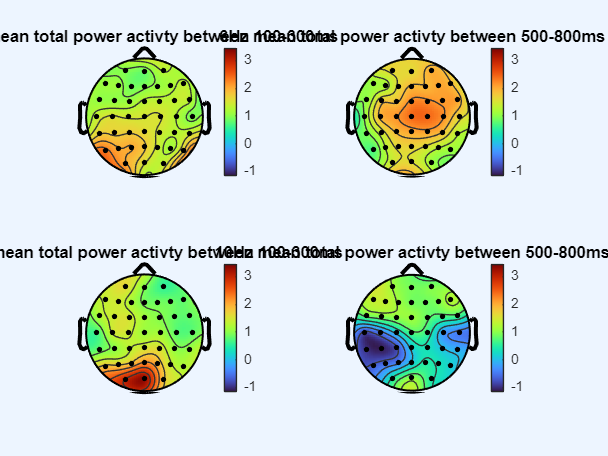

title("10Hz mean total power activty between 500-800ms")

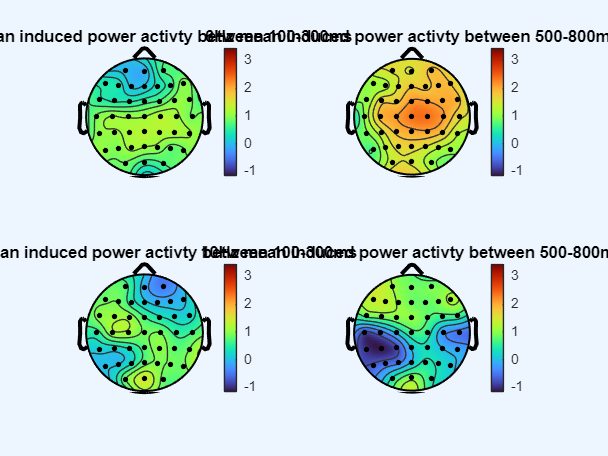

figure;
subplot(221)
topoplot(mean_induced_power(1,:,1), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("6Hz mean induced power activty between 100-300ms")

subplot(222)
topoplot(mean_induced_power(1,:,2), EEG.chanlocs, 'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("6Hz mean induced power activty between 500-800ms")

subplot(223)
topoplot(mean_induced_power(2,:,1), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("10Hz mean induced power activty between 100-300ms")

subplot(224)
topoplot(mean_induced_power(2,:,2), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("10Hz mean induced power activty between 500-800ms")

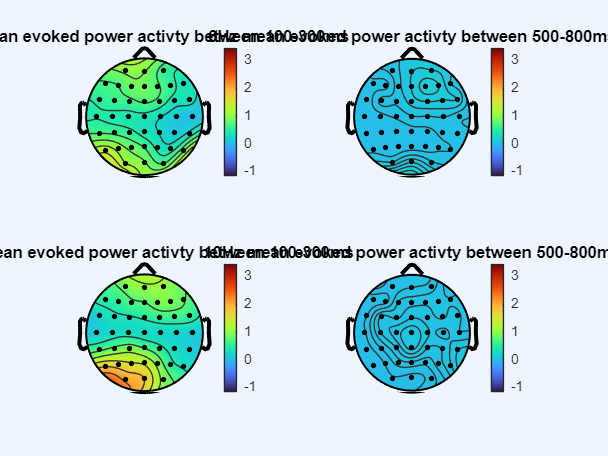

figure;
subplot(221)
topoplot(mean_evoked_power(1,:,1), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("6Hz mean evoked power activty between 100-300ms")

subplot(222)
topoplot(mean_evoked_power(1,:,2), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("6Hz mean evoked power activty between 500-800ms")

subplot(223)
topoplot(mean_evoked_power(2,:,1), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("10Hz mean evoked power activty between 100-300ms")

subplot(224)
topoplot(mean_evoked_power(2,:,2), EEG.chanlocs,'maplimits', clim_all, 'electrodes', 'on', 'plotrad', .50);
cb = colorbar();
title("10Hz mean evoked power activty between 500-800ms")